clear
clc
close all

%% PARAMETERS

params.Lx = 100;
params.Ly = 100;
params.res = 1;

params.victim = [40 60];
params.depth = 2;

params.k = 1;

function [X,Y,Z] = generateAvalancheSurface(Lx,Ly,res)

x = 0:res:Lx;
y = 0:res:Ly;

[X,Y] = meshgrid(x,y);

% base slope (30%)
slope = 0.3*X; 

% random terrain
noise = randn(size(X));

% smooth it (snow is not jagged)
noise = imgaussfilt(noise,5);

% scale amplitude
noise = 1.5*noise;

% final surface
Z = slope + noise;

% --- Add occasional snow mounds ---
numMounds = 7;                 % number of higher snow spots
moundHeight = 1.5;                % max height of mound in meters
moundSpread = 4;                % how wide each mound is (in meters)

for i = 1:numMounds
    % random center location
    cx = rand*Lx;
    cy = rand*Ly;
    
    % Gaussian bump
    Z = Z + moundHeight*exp(-((X-cx).^2 + (Y-cy).^2)/(2*moundSpread^2));
end

end

function B = generateARTVAField(X,Y,victim,depth,altitude,k)

xT = victim(1);
yT = victim(2);

% vertical distance between drone and victim
h = depth + altitude;

% total distance
rho = sqrt((X-xT).^2 + (Y-yT).^2 + h^2);

% magnetic field magnitude
B = k ./ (rho.^3);

end

% GENERATE SURFACE

[X,Y,Z] = generateAvalancheSurface(params.Lx,params.Ly,params.res);

% GENERATE ARTVA FIELD

B = generateARTVAField(X,Y,params.victim,params.depth,0,params.k);

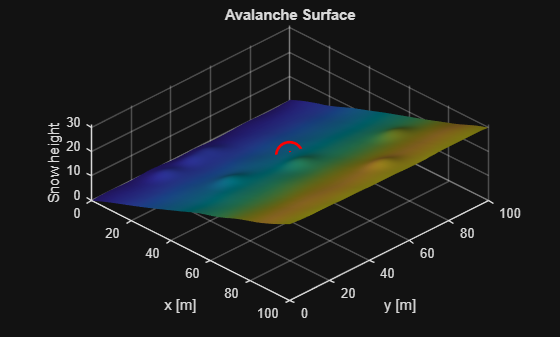

% PLOTS

figure

surf(X,Y,Z,'EdgeColor','none')
colormap(parula)
camlight
lighting phong
title('Avalanche Surface')
xlabel('x [m]')
ylabel('y [m]')
zlabel('Snow height')

hold on
xT = params.victim(1);
yT = params.victim(2);

% surface height
z_surface = interp2(X,Y,Z,xT,yT);

% buried victim position
z_victim = z_surface - params.depth;

plot3(xT,yT,z_victim,...
    'ro','MarkerSize',20,'LineWidth',2)
plot3([xT xT],[yT yT],[z_surface z_victim],'r--','LineWidth',1.5)
axis equal
view(45,30)

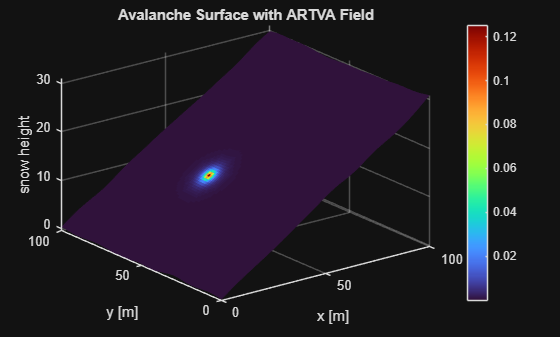

figure

surf(X,Y,Z,B,'EdgeColor','none')

colormap turbo
colorbar

title('Avalanche Surface with ARTVA Field')
xlabel('x [m]')
ylabel('y [m]')
zlabel('snow height')